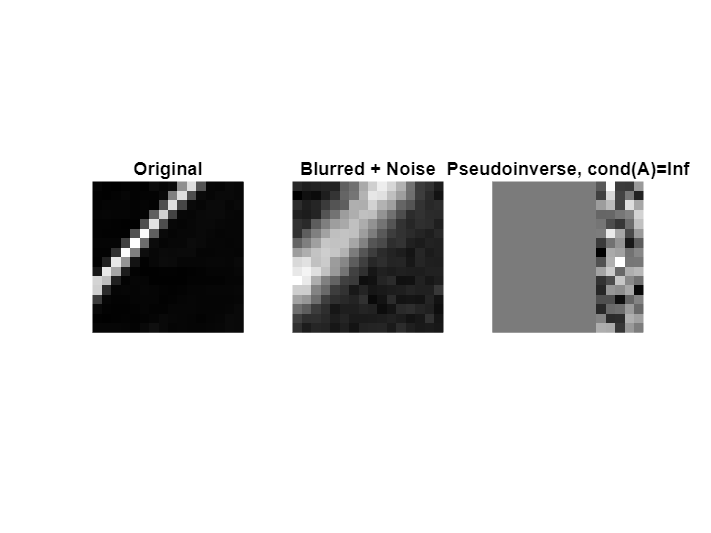

img = im2double(imread('cameraman.tif'));
patch = img(100:115, 100:115);

h = fspecial('gaussian', [9 9], 2);
y = imfilter(patch, h, 'symmetric') + 0.01*randn(size(patch));

A = convmtx2(h, size(patch,1), size(patch,2));
A = A(1:numel(patch), 1:numel(patch));
A = full(A);          % convert sparse → dense
[U,S,V] = svd(A, 'econ');

% [U,S,V] = svd(A, 'econ');
x_pinv = V * diag(1./diag(S)) * U' * y(:);

figure;
subplot(1,3,1), imshow(patch, []), title('Original');
subplot(1,3,2), imshow(y, []), title('Blurred + Noise');
subplot(1,3,3), imshow(reshape(x_pinv, size(patch)), []), ...
    title(['Pseudoinverse, cond(A)=', num2str(cond(A))]);